## Step 4 - 店舗プロファイル分析：規模・特性の詳細調査

% 目的: 異質店舗の理由を探る
% clear; clc; close all;

### 1. データ読み込み

if ~exist('rawData_dailySales', 'var')
    error('rawData_dailySales が見つかりません。');
end

if ~exist('rawData_dailyCustomer', 'var')
    error('rawData_dailyCustomer が見つかりません。');
end

load('step3_results.mat', 'step3Results');
fprintf('✓ Step 3の結果を読み込みました\n');

✓ Step 3の結果を読み込みました



storeList = step3Results.storeList;
patternSimilarity = step3Results.patternSimilarity;
storeTotalSales = step3Results.storeTotalSales;
nStores = length(storeList);

### 2. 店舗別の基本指標を計算

% 初期化
storeMetrics = struct();
storeMetrics.storeCode = storeList;
storeMetrics.totalSales = storeTotalSales;
storeMetrics.patternSimilarity = patternSimilarity;

% 店舗別の詳細指標
storeMetrics.avgDailySales = zeros(nStores, 1);
storeMetrics.nCategories = zeros(nStores, 1);
storeMetrics.nActiveDays = zeros(nStores, 1);
storeMetrics.topCategoryShare = zeros(nStores, 1);
storeMetrics.avgCustomers = zeros(nStores, 1);
storeMetrics.salesPerCustomer = zeros(nStores, 1);

for s = 1:nStores
    storeCode = storeList(s);
    
    % 販売データ
    storeData = rawData_dailySales(rawData_dailySales.BookstoreCode == storeCode, :);
    
    if isempty(storeData)
        continue;
    end
    
    % 営業日数
    activeDays = length(unique(storeData.Date));
    storeMetrics.nActiveDays(s) = activeDays;
    
    % 日平均売上
    storeMetrics.avgDailySales(s) = storeTotalSales(s) / activeDays;
    
    % 取扱カテゴリ数
    nCat = length(unique(storeData.MajorCategory));
    storeMetrics.nCategories(s) = nCat;
    
    % カテゴリ別売上
    catSales = grpstats(storeData, 'MajorCategory', 'sum', ...
        'DataVars', 'POSSalesVolume');
    if height(catSales) > 0
        topShare = max(catSales.sum_POSSalesVolume) / storeTotalSales(s);
        storeMetrics.topCategoryShare(s) = topShare;
    end
    
    % 来客数データ
    customerData = rawData_dailyCustomer(...
        rawData_dailyCustomer.BookstoreCode == storeCode, :);
    
    if ~isempty(customerData)
        avgCust = mean(customerData.CustomerCount);
        storeMetrics.avgCustomers(s) = avgCust;
        
        if avgCust > 0
            storeMetrics.salesPerCustomer(s) = storeMetrics.avgDailySales(s) / avgCust;
        end
    end
end

fprintf('指標計算完了\n');

指標計算完了


### 3. 店舗の分類

% 売上規模による分類（3段階）
salesThresholds = quantile(storeTotalSales, [0.33, 0.67]);
storeSize = zeros(nStores, 1);
storeSize(storeTotalSales <= salesThresholds(1)) = 1; % 小規模
storeSize(storeTotalSales > salesThresholds(1) & ...
          storeTotalSales <= salesThresholds(2)) = 2; % 中規模
storeSize(storeTotalSales > salesThresholds(2)) = 3; % 大規模

fprintf('小規模店舗: %d店舗（売上 ≤ %.0f冊）\n', ...
    sum(storeSize == 1), salesThresholds(1));

小規模店舗: 12店舗（売上 ≤ 99293冊）


fprintf('中規模店舗: %d店舗（%.0f < 売上 ≤ %.0f冊）\n', ...
    sum(storeSize == 2), salesThresholds(1), salesThresholds(2));

中規模店舗: 11店舗（99293 < 売上 ≤ 145117冊）


fprintf('大規模店舗: %d店舗（売上 > %.0f冊）\n', ...
    sum(storeSize == 3), salesThresholds(2));

大規模店舗: 12店舗（売上 > 145117冊）



storeMetrics.size = storeSize;

### 4. 異質店舗（店舗26）の詳細プロファイル

store26idx = find(storeList == 26);
if ~isempty(store26idx)
    fprintf('店舗26の特徴:\n');
    fprintf('  総売上: %d冊（35店舗中最小級）\n', storeTotalSales(store26idx));
    fprintf('  日平均売上: %.1f冊/日\n', storeMetrics.avgDailySales(store26idx));
    fprintf('  営業日数: %d日\n', storeMetrics.nActiveDays(store26idx));
    fprintf('  取扱カテゴリ数: %d\n', storeMetrics.nCategories(store26idx));
    fprintf('  TOP1カテゴリシェア: %.1f%%\n', ...
        storeMetrics.topCategoryShare(store26idx) * 100);
    fprintf('  平均来客数: %.1f人/日\n', storeMetrics.avgCustomers(store26idx));
    fprintf('  客単価: %.2f冊/人\n', storeMetrics.salesPerCustomer(store26idx));
    
    % カテゴリ別売上TOP5
    store26data = rawData_dailySales(rawData_dailySales.BookstoreCode == 26, :);
    catSales26 = grpstats(store26data, 'MajorCategory', 'sum', ...
        'DataVars', 'POSSalesVolume');
    catSales26 = sortrows(catSales26, 'sum_POSSalesVolume', 'descend');
    
    fprintf('\n  TOP5カテゴリ:\n');
    for i = 1:min(5, height(catSales26))
        fprintf('    %d. %s: %d冊 (%.1f%%)\n', i, ...
            char(catSales26.MajorCategory(i)), ...
            catSales26.sum_POSSalesVolume(i), ...
            catSales26.sum_POSSalesVolume(i) / storeTotalSales(store26idx) * 100);
    end
end

店舗26の特徴:


  総売上: 8438冊（35店舗中最小級）


  日平均売上: 32.2冊/日


  営業日数: 262日


  取扱カテゴリ数: 216


  TOP1カテゴリシェア: 26.6%


  平均来客数: 21.5人/日


  客単価: 1.50冊/人



  TOP5カテゴリ:


    1. 語学: 2247冊 (26.6%)
    2. 生活: 1282冊 (15.2%)
    3. 工学: 1246冊 (14.8%)
    4. 月刊誌: 690冊 (8.2%)
    5. ビジネス: 356冊 (4.2%)


### 5. 規模別のパターン一致度

for sz = 1:3
    sizeIdx = find(storeSize == sz & step3Results.storeValidFlags);
    if isempty(sizeIdx)
        continue;
    end
    
    sizeName = {'小規模', '中規模', '大規模'};
    avgSim = mean(patternSimilarity(sizeIdx));
    avgSales = mean(storeTotalSales(sizeIdx));
    
    fprintf('%s店舗: 平均一致度=%.3f, 平均売上=%.0f冊\n', ...
        sizeName{sz}, avgSim, avgSales);
end

小規模店舗: 平均一致度=0.583, 平均売上=61557冊
中規模店舗: 平均一致度=0.770, 平均売上=132378冊
大規模店舗: 平均一致度=0.760, 平均売上=208394冊


### 6. 客単価とパターン一致度の関係

validIdx = storeMetrics.salesPerCustomer > 0 & ...
           step3Results.storeValidFlags & ...
           ~isnan(patternSimilarity);

if sum(validIdx) > 3
    corrMat = corrcoef(storeMetrics.salesPerCustomer(validIdx), ...
                       patternSimilarity(validIdx));
    fprintf('客単価 vs パターン一致度の相関: %.3f\n', corrMat(1, 2));
end

客単価 vs パターン一致度の相関: 0.230


### 7. 可視化

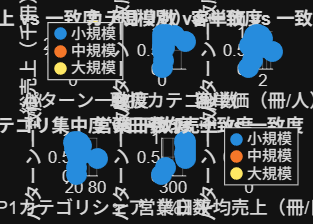

% 図1: 店舗プロファイルの散布図マトリクス
figure('Name', '店舗プロファイル分析', 'Position', [100 100 1400 1000]);

validStores = step3Results.storeValidFlags;
colorMap = lines(3);

% サブプロット1: 売上 vs 一致度（規模別）
subplot(2, 3, 1);
hold on;
for sz = 1:3
    idx = storeSize == sz & validStores;
    scatter(patternSimilarity(idx), storeTotalSales(idx)/1000, 100, ...
        colorMap(sz, :), 'filled');
end
xlabel('パターン一致度');
ylabel('総売上（千冊）');
title('売上 vs 一致度（規模別）');
legend('小規模', '中規模', '大規模', 'Location', 'best');
grid on;

% サブプロット2: カテゴリ数 vs 一致度
subplot(2, 3, 2);
scatter(storeMetrics.nCategories(validStores), ...
    patternSimilarity(validStores), 100, 'filled');
xlabel('取扱カテゴリ数');
ylabel('パターン一致度');
title('カテゴリ数 vs 一致度');
grid on;

% サブプロット3: 客単価 vs 一致度
subplot(2, 3, 3);
validCustomer = storeMetrics.salesPerCustomer > 0 & validStores;
scatter(storeMetrics.salesPerCustomer(validCustomer), ...
    patternSimilarity(validCustomer), 100, 'filled');
xlabel('客単価（冊/人）');
ylabel('パターン一致度');
title('客単価 vs 一致度');
grid on;

% サブプロット4: TOP1シェア vs 一致度
subplot(2, 3, 4);
scatter(storeMetrics.topCategoryShare(validStores) * 100, ...
    patternSimilarity(validStores), 100, 'filled');
xlabel('TOP1カテゴリシェア（%）');
ylabel('パターン一致度');
title('カテゴリ集中度 vs 一致度');
grid on;

% サブプロット5: 営業日数 vs 一致度
subplot(2, 3, 5);
scatter(storeMetrics.nActiveDays(validStores), ...
    patternSimilarity(validStores), 100, 'filled');
xlabel('営業日数');
ylabel('パターン一致度');
title('営業日数 vs 一致度');
grid on;

% サブプロット6: 日平均売上 vs 一致度
subplot(2, 3, 6);
hold on;
for sz = 1:3
    idx = storeSize == sz & validStores;
    scatter(storeMetrics.avgDailySales(idx), ...
        patternSimilarity(idx), 100, colorMap(sz, :), 'filled');
end
xlabel('日平均売上（冊/日）');
ylabel('パターン一致度');
title('日平均売上 vs 一致度（規模別）');
legend('小規模', '中規模', '大規模', 'Location', 'best');
grid on;

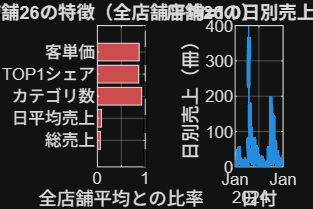


% 図2: 店舗26の特徴分析
figure('Name', '異質店舗26の特徴', 'Position', [150 150 1200 800]);

% 全店舗との比較
metrics = {'総売上', '日平均売上', 'カテゴリ数', 'TOP1シェア', '客単価'};
store26values = [
    storeTotalSales(store26idx) / mean(storeTotalSales);
    storeMetrics.avgDailySales(store26idx) / mean(storeMetrics.avgDailySales);
    storeMetrics.nCategories(store26idx) / mean(storeMetrics.nCategories);
    storeMetrics.topCategoryShare(store26idx) / mean(storeMetrics.topCategoryShare);
    storeMetrics.salesPerCustomer(store26idx) / mean(storeMetrics.salesPerCustomer(validIdx))
];

subplot(1, 2, 1);
barh(1:5, store26values, 'FaceColor', [0.8 0.3 0.3]);
yticks(1:5);
yticklabels(metrics);
xlabel('全店舗平均との比率');
title('店舗26の特徴（全店舗平均=1.0）');
grid on;
xline(1, 'k--', 'LineWidth', 2);

% 店舗26の時系列売上
subplot(1, 2, 2);
store26daily = grpstats(store26data, 'Date', 'sum', 'DataVars', 'POSSalesVolume');
plot(store26daily.Date, store26daily.sum_POSSalesVolume, 'LineWidth', 2);
xlabel('日付');
ylabel('日別売上（冊）');
title('店舗26の日別売上推移');
grid on;

### 8. 結果の保存

storeMetrics.storeName = arrayfun(@(x) sprintf('店舗%d', x), ...
    storeList, 'UniformOutput', false);

step4Results.storeMetrics = storeMetrics;
step4Results.storeSize = storeSize;
step4Results.salesThresholds = salesThresholds;

save('step4_results.mat', 'step4Results');
fprintf('\n✓ 結果を step4_results.mat に保存しました\n');


✓ 結果を step4_results.mat に保存しました


fprintf('\n=== Step 4 完了 ===\n');


=== Step 4 完了 ===
